dirpath = pwd;

s = dir([dirpath, '/*.h5']);
filename_list = {s.name};
fprintf("%s\n", s.name)

cell1_iv_2017-09-20_0001-0012.h5
cell_continuous_2017-09-20_002_0001.h5
cell_iv_2017-09-20_002_0001-0011.h5
cell_kcl_2017-09-20_002_0001.h5
cell_kcl_imaging_2017-09-20_002_0001.h5
cell_kcl_imaging_2017-09-20_002_0002.h5
cell_kcl_imaging_2017-09-20_003_0001.h5
cell_kcl_imaging_2017-09-20_003_0002.h5


n_file = length(filename_list)

n_file = 8

% List all the files loaded and see # of sweeps
loaded_files = 1:n_file;
%
data = cell(1, length(loaded_files));
for i = loaded_files
    data{i} = ws.loadDataFile(filename_list{i});
    % I modified the function 'loadDataFile.m': NAIChannels to NAITerminals 2017 0921 Juyoung
    fprintf("%d: %s\n",i, filename_list{i});
    %disp(data{i})
end

1: cell1_iv_2017-09-20_0001-0012.h5
2: cell_continuous_2017-09-20_002_0001.h5
3: cell_iv_2017-09-20_002_0001-0011.h5
4: cell_kcl_2017-09-20_002_0001.h5
5: cell_kcl_imaging_2017-09-20_002_0001.h5
6: cell_kcl_imaging_2017-09-20_002_0002.h5
7: cell_kcl_imaging_2017-09-20_003_0001.h5
8: cell_kcl_imaging_2017-09-20_003_0002.h5


**data{i} - hedaer + sweep X n times**

% further insepction of data
for i = loaded_files
    fprintf("%d: %s\n",i, filename_list{i});
    fprintf("           header.SweepDuration: %.2f (s)\n", data{i}.header.SweepDuration);
    fprintf("    header.Acquisition.Duration: %.2f (s)\n", data{i}.header.Acquisition.Duration);
end

1: cell1_iv_2017-09-20_0001-0012.h5


           header.SweepDuration: 1.50 (s)


    header.Acquisition.Duration: 1.50 (s)


2: cell_continuous_2017-09-20_002_0001.h5


           header.SweepDuration: Inf (s)


    header.Acquisition.Duration: Inf (s)


3: cell_iv_2017-09-20_002_0001-0011.h5


           header.SweepDuration: 1.50 (s)


    header.Acquisition.Duration: 1.50 (s)


4: cell_kcl_2017-09-20_002_0001.h5


           header.SweepDuration: Inf (s)


    header.Acquisition.Duration: Inf (s)


5: cell_kcl_imaging_2017-09-20_002_0001.h5


           header.SweepDuration: Inf (s)


    header.Acquisition.Duration: Inf (s)


6: cell_kcl_imaging_2017-09-20_002_0002.h5


           header.SweepDuration: 300.00 (s)


    header.Acquisition.Duration: 300.00 (s)


7: cell_kcl_imaging_2017-09-20_003_0001.h5


           header.SweepDuration: 300.00 (s)


    header.Acquisition.Duration: 300.00 (s)


8: cell_kcl_imaging_2017-09-20_003_0002.h5


           header.SweepDuration: 300.00 (s)


    header.Acquisition.Duration: 300.00 (s)


% choose interesting cells or recordings
file_selected = [3, 4, 5, 6, 7, 8];
file_selected = loaded_files;
voltage = cell(1,numel(file_selected));
current = cell(1,numel(file_selected));
times = cell(1,numel(file_selected));

1-th file: cell1_iv_2017-09-20_0001-0012.h5


n_sampling = 30000

n_ch = 2

2-th file: cell_continuous_2017-09-20_002_0001.h5


n_sampling = 1284667

n_ch = 2

3-th file: cell_iv_2017-09-20_002_0001-0011.h5


n_sampling = 30000

n_ch = 2

4-th file: cell_kcl_2017-09-20_002_0001.h5


n_sampling = 3837074

n_ch = 2

5-th file: cell_kcl_imaging_2017-09-20_002_0001.h5


n_sampling = 74442

n_ch = 2

6-th file: cell_kcl_imaging_2017-09-20_002_0002.h5


n_sampling = 1523467

n_ch = 2

7-th file: cell_kcl_imaging_2017-09-20_003_0001.h5


n_sampling = 6000000

n_ch = 2

8-th file: cell_kcl_imaging_2017-09-20_003_0002.h5


n_sampling = 6000000

n_ch = 2

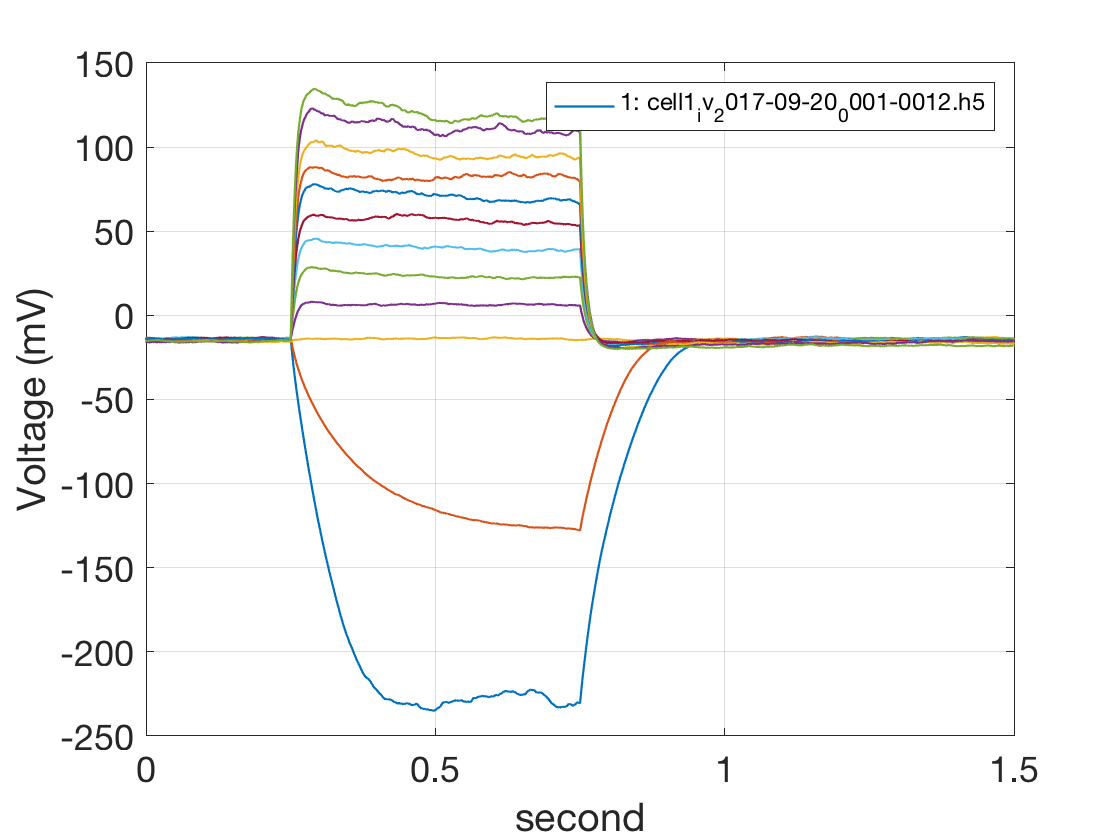

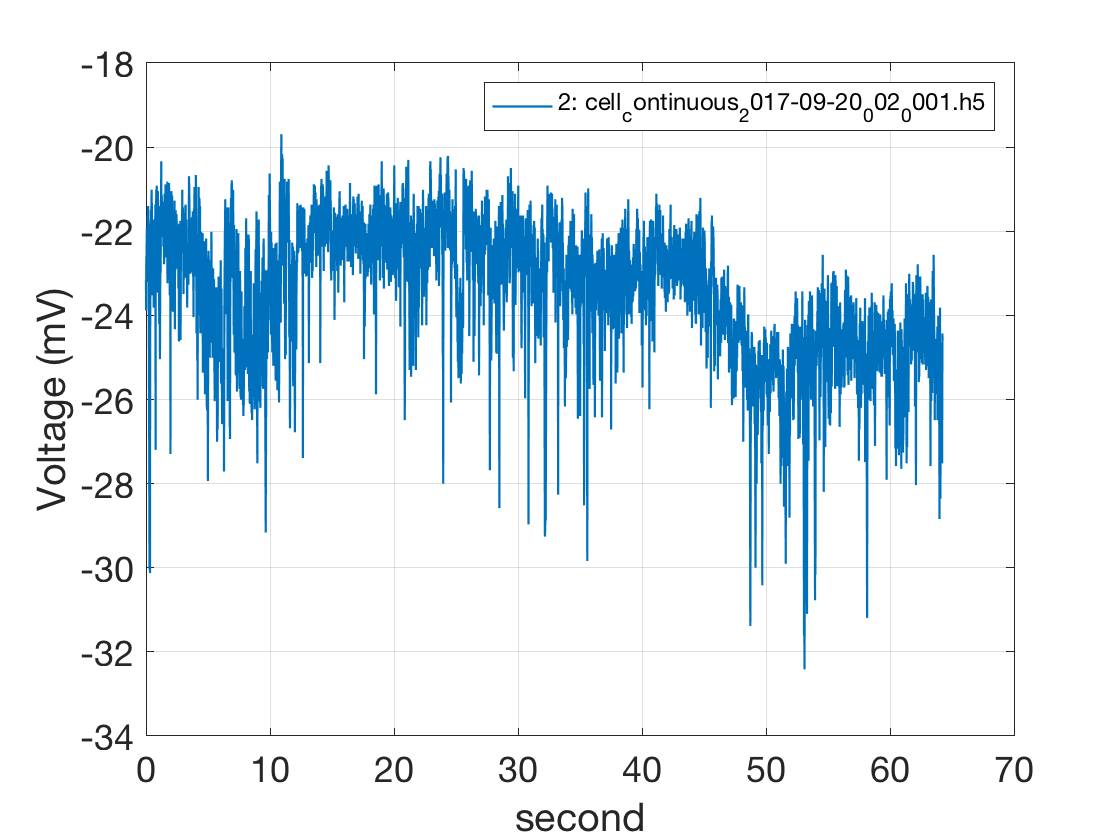

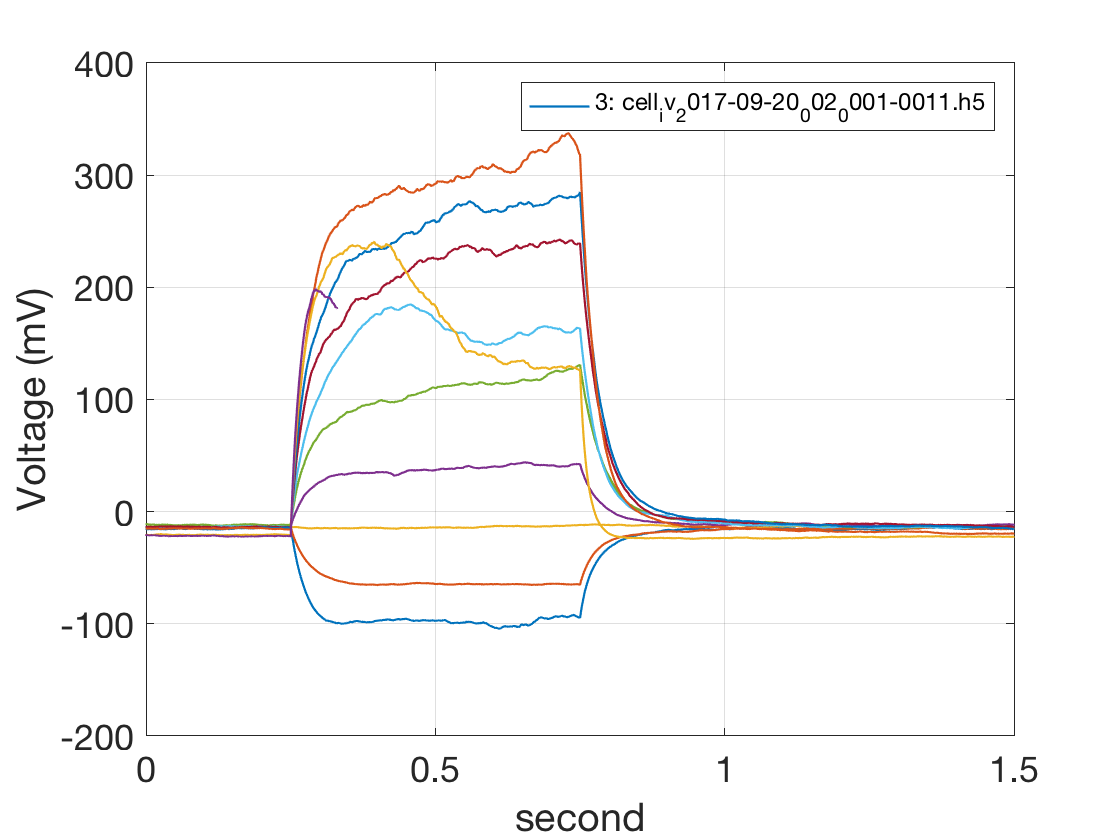

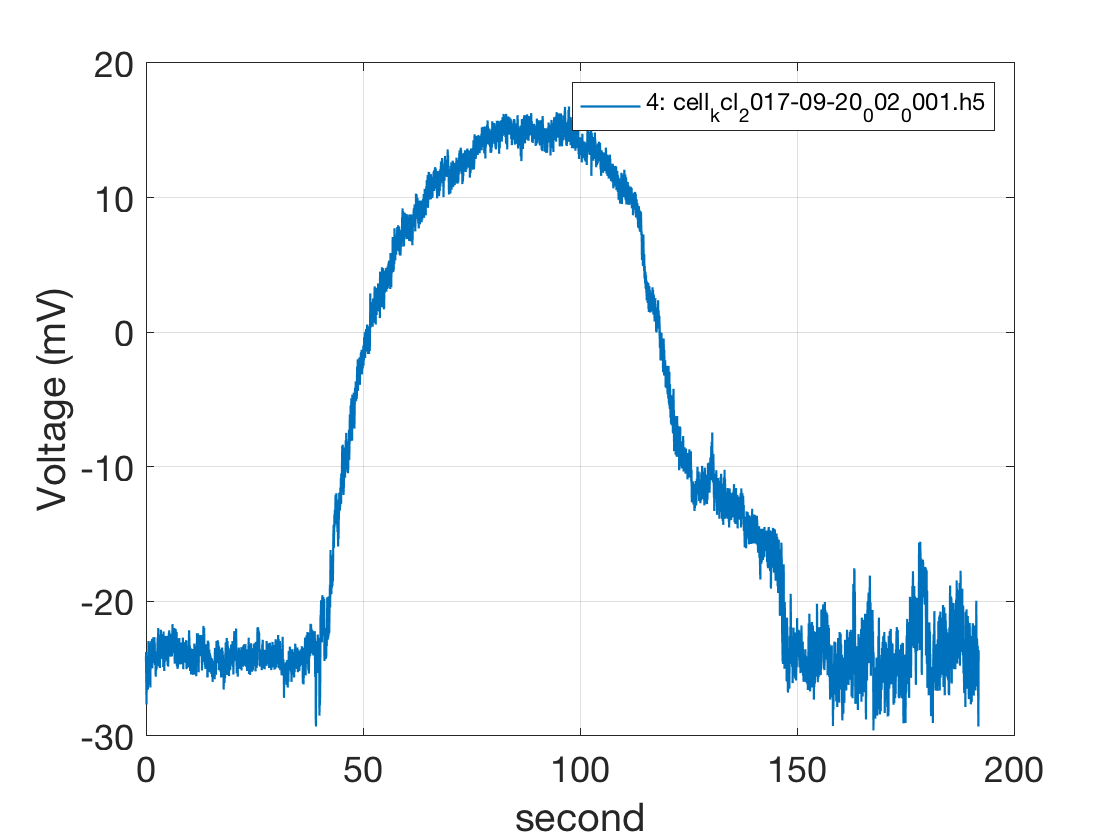

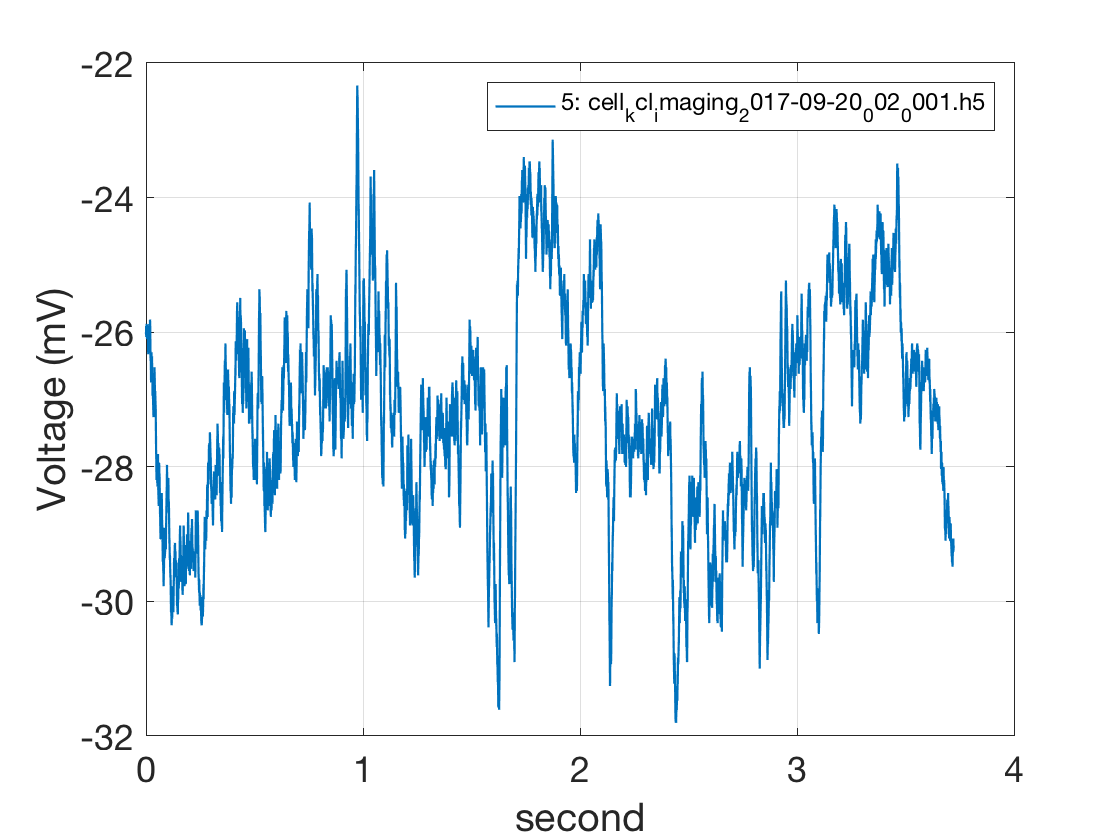

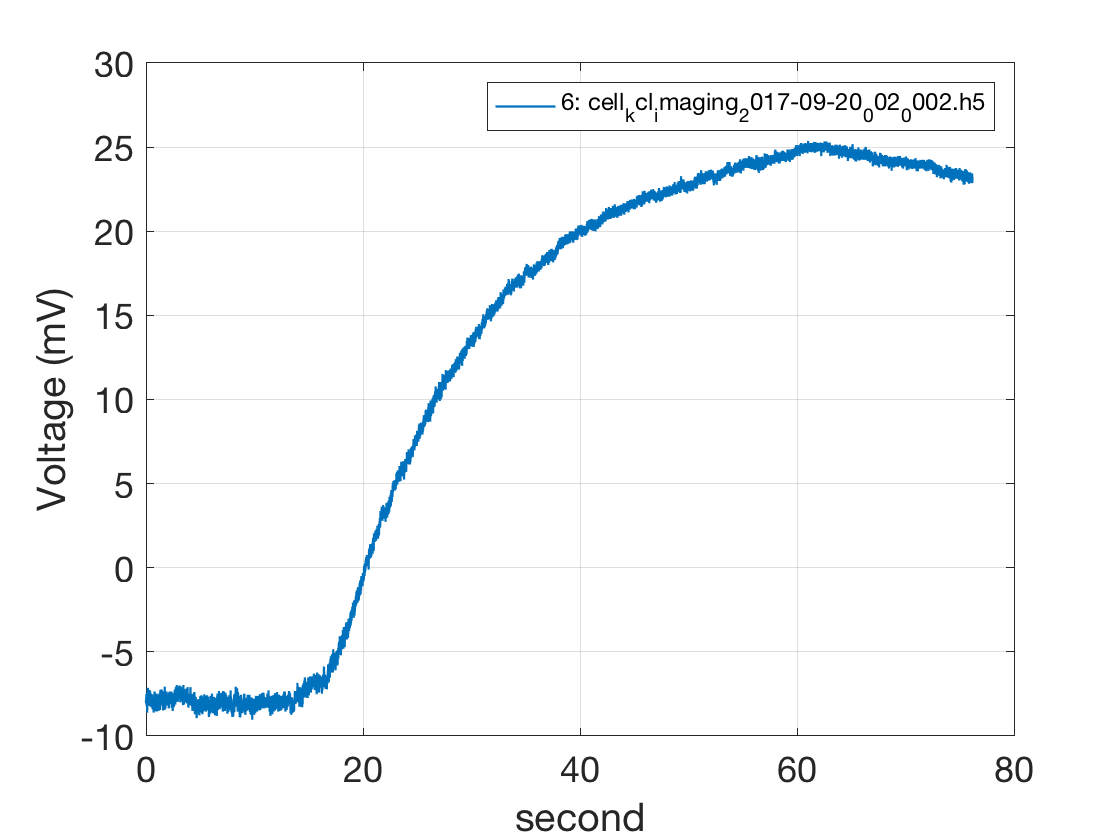

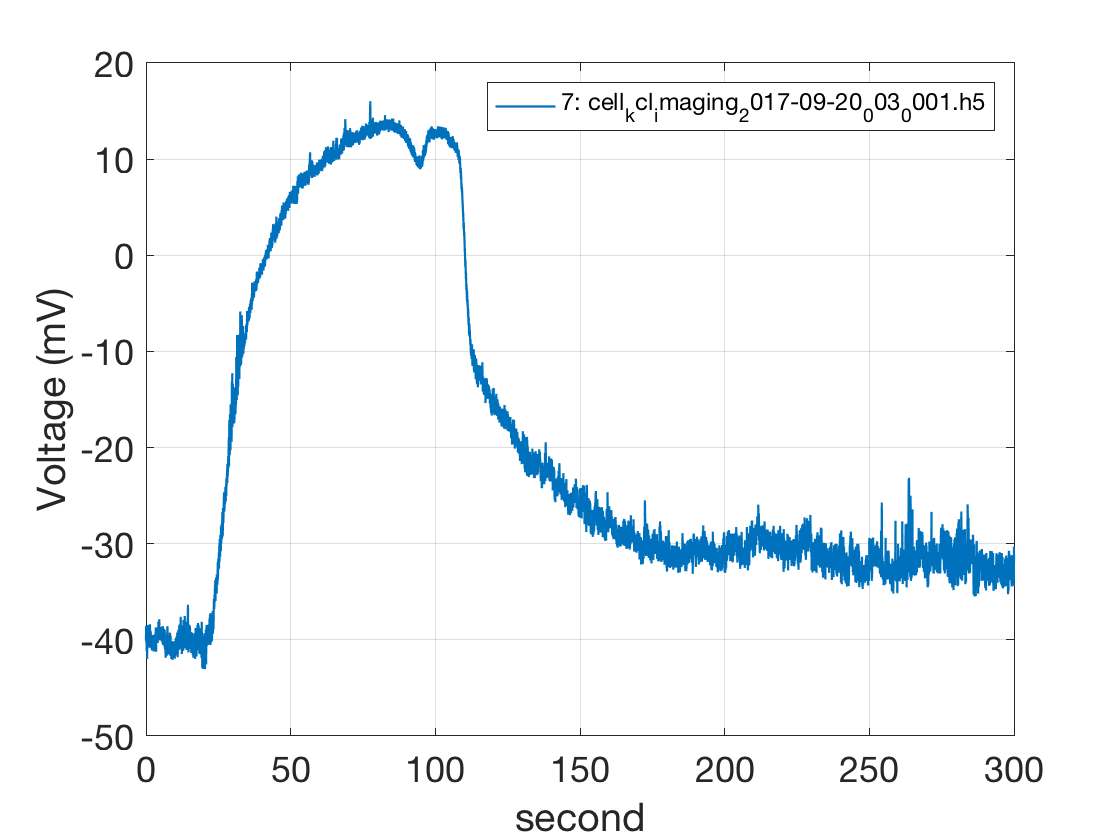

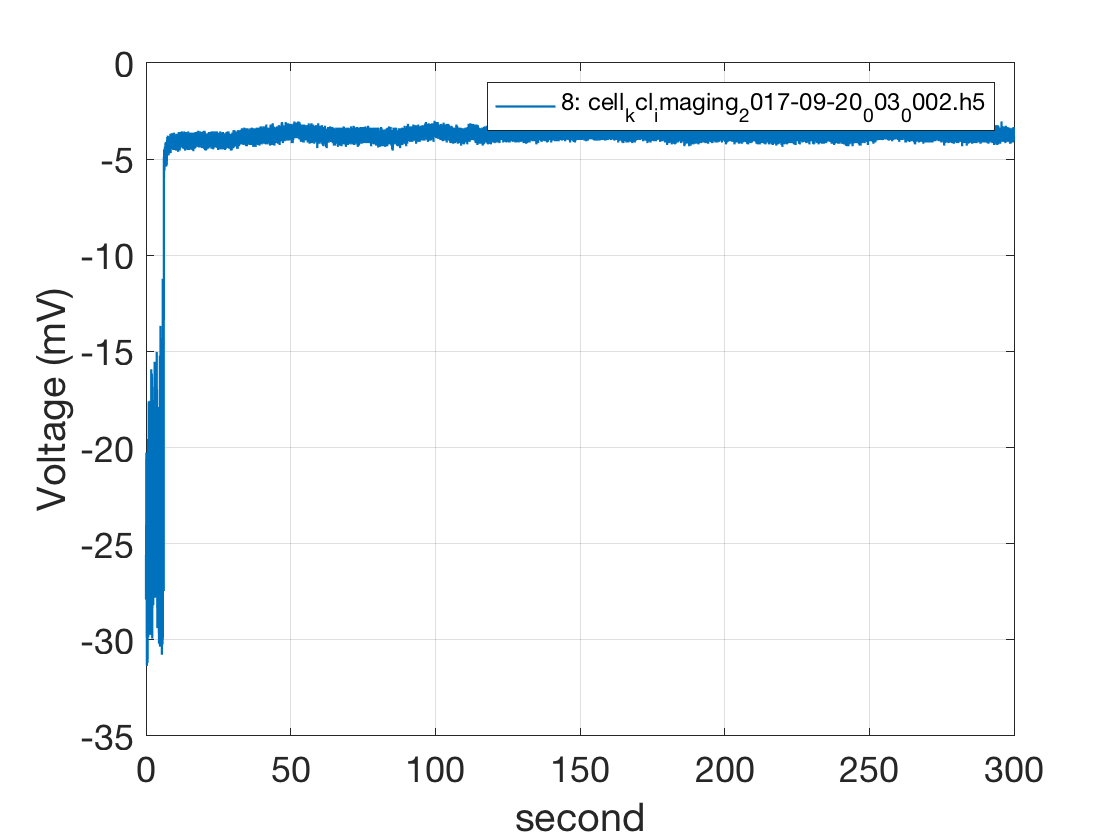

% cell (or recording) # -> cell array
% sweeps -> array
% Initialize data matrix with zeros instead of empty matrix in case sampling varied over multiple sweeps
for i = file_selected
    fprintf("%d-th file: %s\n", i, filename_list{i});
    sweep_names = fieldnames(data{i});
    % exclude 'header' field
    sweep_names = sweep_names(2:end);
    %
    n_sweeps = length(sweep_names);
    % Initialize data matrix with zeros instead of empty matrix in case sampling varied over multiple sweeps
    [n_sampling, n_ch] = size(getfield(data{i}, sweep_names{1}, 'analogScans')) % guess by first sweep data
    vol_sweeps = zeros(n_sampling,n_sweeps);
    cur_sweeps = zeros(n_sampling,n_sweeps);
    % Assume 20K sampling !!!
    times{i} = (1:n_sampling)*0.00005; 
    figure;
    %
    for j = 1:n_sweeps
        sweep = getfield(data{i}, sweep_names{j});
        
        vol_temp = sweep.analogScans(:,1); % voltage channel
        cur_temp = sweep.analogScans(:,2); % current channel
        
        n_sampling = length(sweep.analogScans);
        % Assume 20K sampling !!!
        times_temp = (1:n_sampling)*0.00005; 
        % simple plot
        plot(times_temp, vol_temp, 'LineWidth', 1.1); grid on; hold on;
        xlabel('second'); ylabel('Voltage (mV)');
        ax = gca; Fontsize = 18;
        ax.XAxis.FontSize = Fontsize;
        ax.YAxis.FontSize = Fontsize;
        %
        vol_sweeps(1:n_sampling, j) = vol_temp;
        cur_sweeps(1:n_sampling, j) = cur_temp;
    end
    voltage{i} = vol_sweeps;
    current{i} = cur_sweeps;
    hold off;
    ax = legend([num2str(i),': ',filename_list{i}]);
    ax.FontSize=12;
end

% imaging data
% !! change path
dirpath = pwd

dirpath = '/Users/peterfish/Documents/1__Retina_Study/DATA_2017/0920 RGC recording/cell_kcl_imaging_2017-09-20_003_0001'

% Get file list
s = dir([dirpath, '/*.tif']);
% Convert the name field into cell array
file_list = {s.name};
% Print filenames
fprintf("%s\n", s.name);

cell_kcl_imaging_2017-09-20_003_00001_00001.tif
cell_kcl_imaging_2017-09-20_003_00001_00002.tif
cell_kcl_imaging_2017-09-20_003_00001_00003.tif
cell_kcl_imaging_2017-09-20_003_00001_00004.tif
cell_kcl_imaging_2017-09-20_003_00001_00005.tif
cell_kcl_imaging_2017-09-20_003_00001_00006.tif
cell_kcl_imaging_2017-09-20_003_00001_00007.tif
cell_kcl_imaging_2017-09-20_003_00001_00008.tif
cell_kcl_imaging_2017-09-20_003_00001_00009.tif
cell_kcl_imaging_2017-09-20_003_00001_00010.tif
cell_kcl_imaging_2017-09-20_003_00001_00011.tif
cell_kcl_imaging_2017-09-20_003_00001_00012.tif
cell_kcl_imaging_2017-09-20_003_00001_00013.tif
cell_kcl_imaging_2017-09-20_003_00001_00014.tif
cell_kcl_imaging_2017-09-20_003_00001_00015.tif
cell_kcl_imaging_2017-09-20_003_00001_00016.tif
cell_kcl_imaging_2017-09-20_003_00001_00017.tif
cell_kcl_imaging_2017-09-20_003_00001_00018.tif
cell_kcl_imaging_2017-09-20_003_00001_00019.tif
cell_kcl_imaging_2017-09-20_003_00001_00020.tif
cell_kcl_imaging_2017-09-20_003_00001_00

n_files = numel(file_list);

Elapsed time is 0.414848 seconds.


% Inspection of one file (i=50th file?)
i=50; 
filename = [dirpath,'/',file_list{i}];
%
img = ScanImageTiffReader(filename);
header = img.metadata;
vol = img.data;
[row, col, frames] = size(vol);

str_info = 'SI.hScan2D.logFramesPerFile = ';
str_info = 'SI.hChannels.channelSave = ';
loc = strfind(header, str_info);

str_lines = splitlines(header(loc:end));

()-indexing must appear last in an index expression.

str_lines{1}

ans = 'SI.hChannels.channelSave = [3;4]'

sscanf(str_lines{1}, [str_info, '%f'])

help sscanf

 sscanf Read string or character vector as formatted data
    [A,COUNT,ERRMSG,NEXTINDEX] = sscanf(S,FORMAT,SIZE) reads text from
    MATLAB variable S, converts it according to the format specified by
    FORMAT, and returns it in matrix A. S can be a character vector or a 
    string scalar. COUNT returns the number of elements successfully read. 
    ERRMSG returns an error message if an error occurred or an empty 
    character vector if an error did not occur. NEXTINDEX is an optional 
    output argument specifying one more than the number of characters scanned 
    in S.
 
    sscanf is the same as FSCANF except that it reads the data from
    a MATLAB variable rather than reading it from a file.
    
    SIZE is optional; it puts a limit on the number of elements that
    can be scanned from S; if not specified, sscanf reads to the end of S;
    if specified, valid entries are: 
 
        N      read at most N e

[row  col  d3  d4] = [256  256  30  1]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]


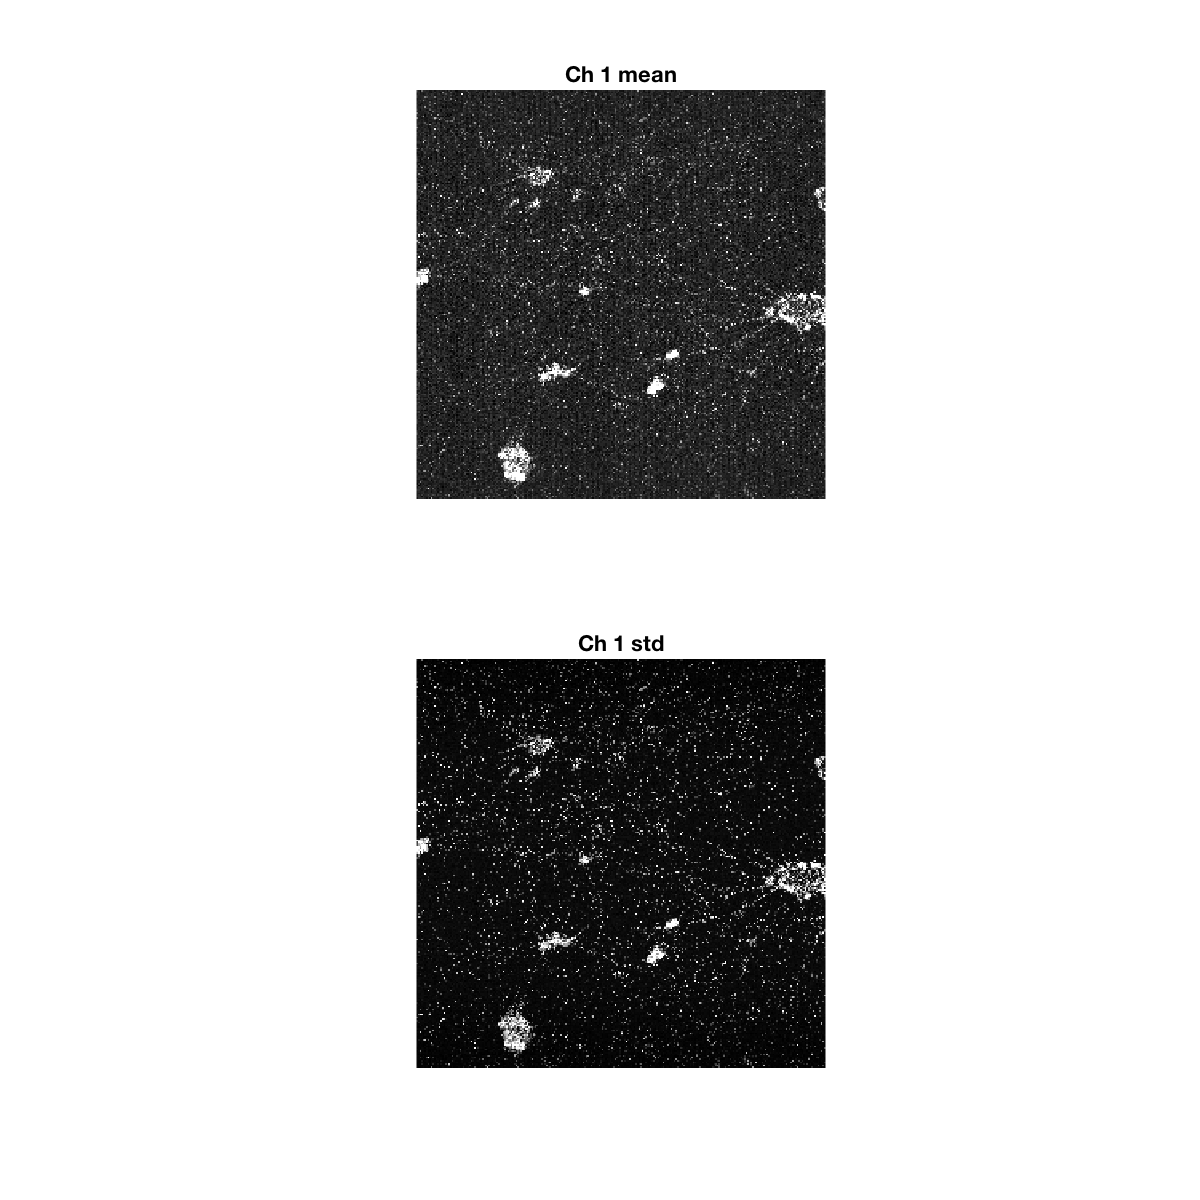

% dim for frame?
% e.g. SI.hScan2D.logFramesPerFile = 30;
f_dim = 3;
n_frames = dim_ch1(f_dim);

% Assume Ch #
% e.g. SI.hChannels.channelSave = [3;4]
N_ch = 2;

% de-interleave into channels
id_ch = mod((1:frames)-1, N_ch)+1;
ch_1_AI = vol(:,:,id_ch==1); % Analog input
ch_2_AI = vol(:,:,id_ch==2);

% for all channels
AI_ch = cell(N_ch, 1);
for i=1:N_ch
    AI_ch{i} = vol(:,:,id_ch==i); % Analog input
end

% check the image (any channels?)
figure; [mean_vol_ch1, std_vol_ch1] = myimgstat(ch_1_AI);

[row  col  d3  d4] = [256  256  30  1]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]


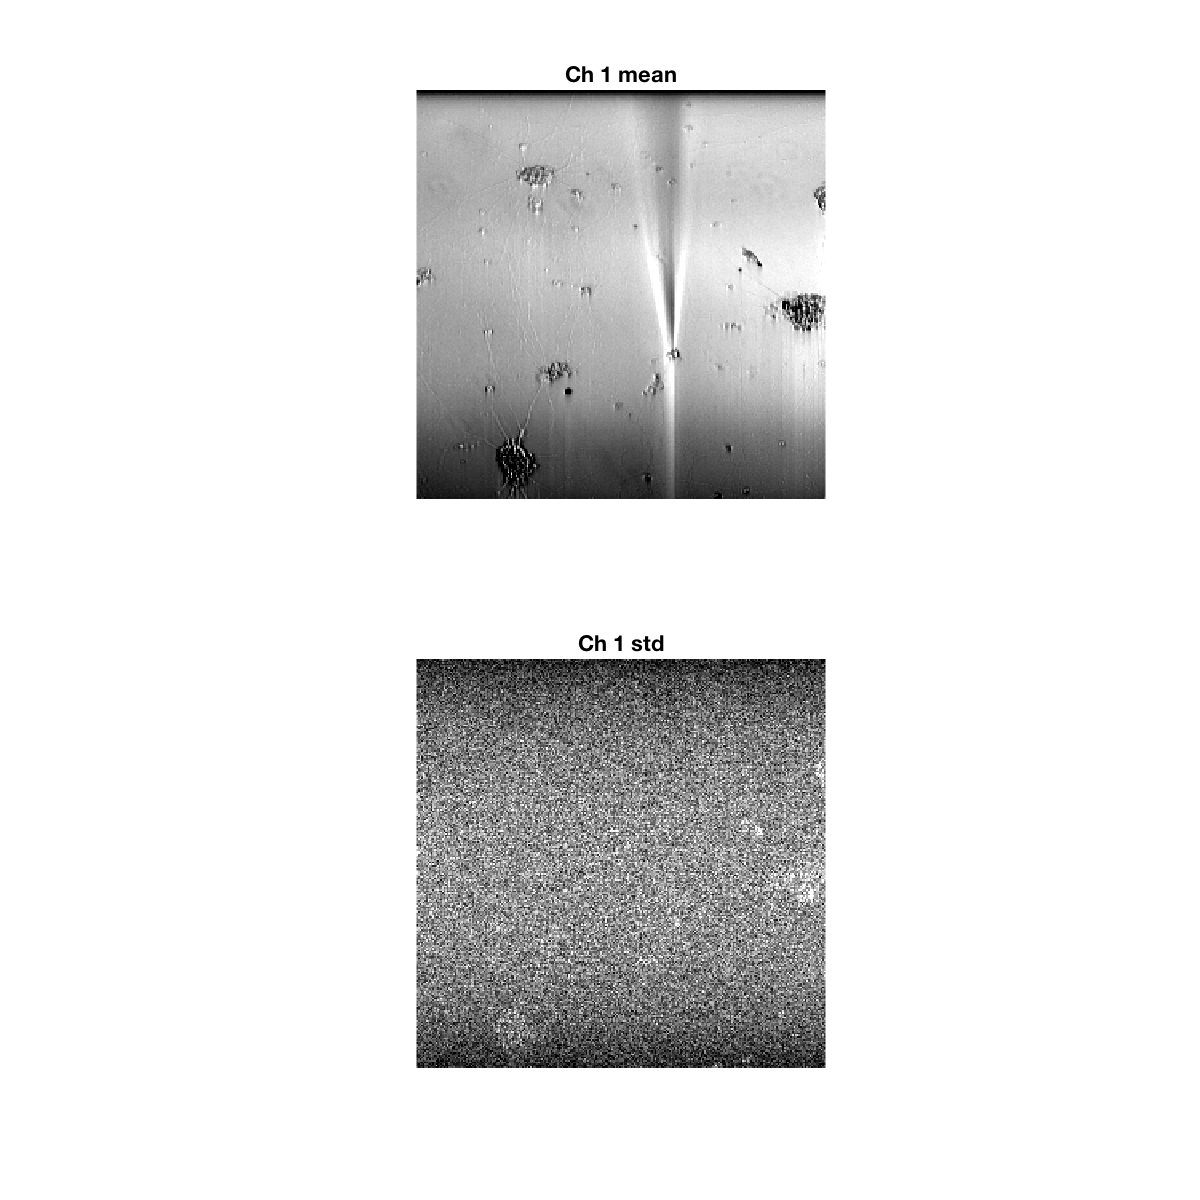

figure; [mean_vol_ch2, std_vol_ch2] = myimgstat(ch_2_AI);

% empty Vol
%img = zeros(d(1),d(2),d(3)*N);
%N_tot_frame = N*d(3);

% if frames are distributed over multiple files, merge into one matrix
ch1 = []; ch2 = []; ch3 = [];
for i=1:n_files
    filename = [dirpath,'/',file_list{i}];
    vol = ScanImageTiffReader(filename).data();
    ch1_vol = vol(:,:,id_ch==1); % Analog input
    ch2_vol = vol(:,:,id_ch==2);
    %
    ch1 = cat(3, ch1, ch1_vol);
    ch2 = cat(3, ch2, ch2_vol);
    %i_frame = (i-1)*d(3)+1; 
    %img(:,:,i_frame:(i_frame+d(3)-1)) = ScanImageTiffReader(filename).data();
end

[row  col  d3  d4] = [256  256  9000  1]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]


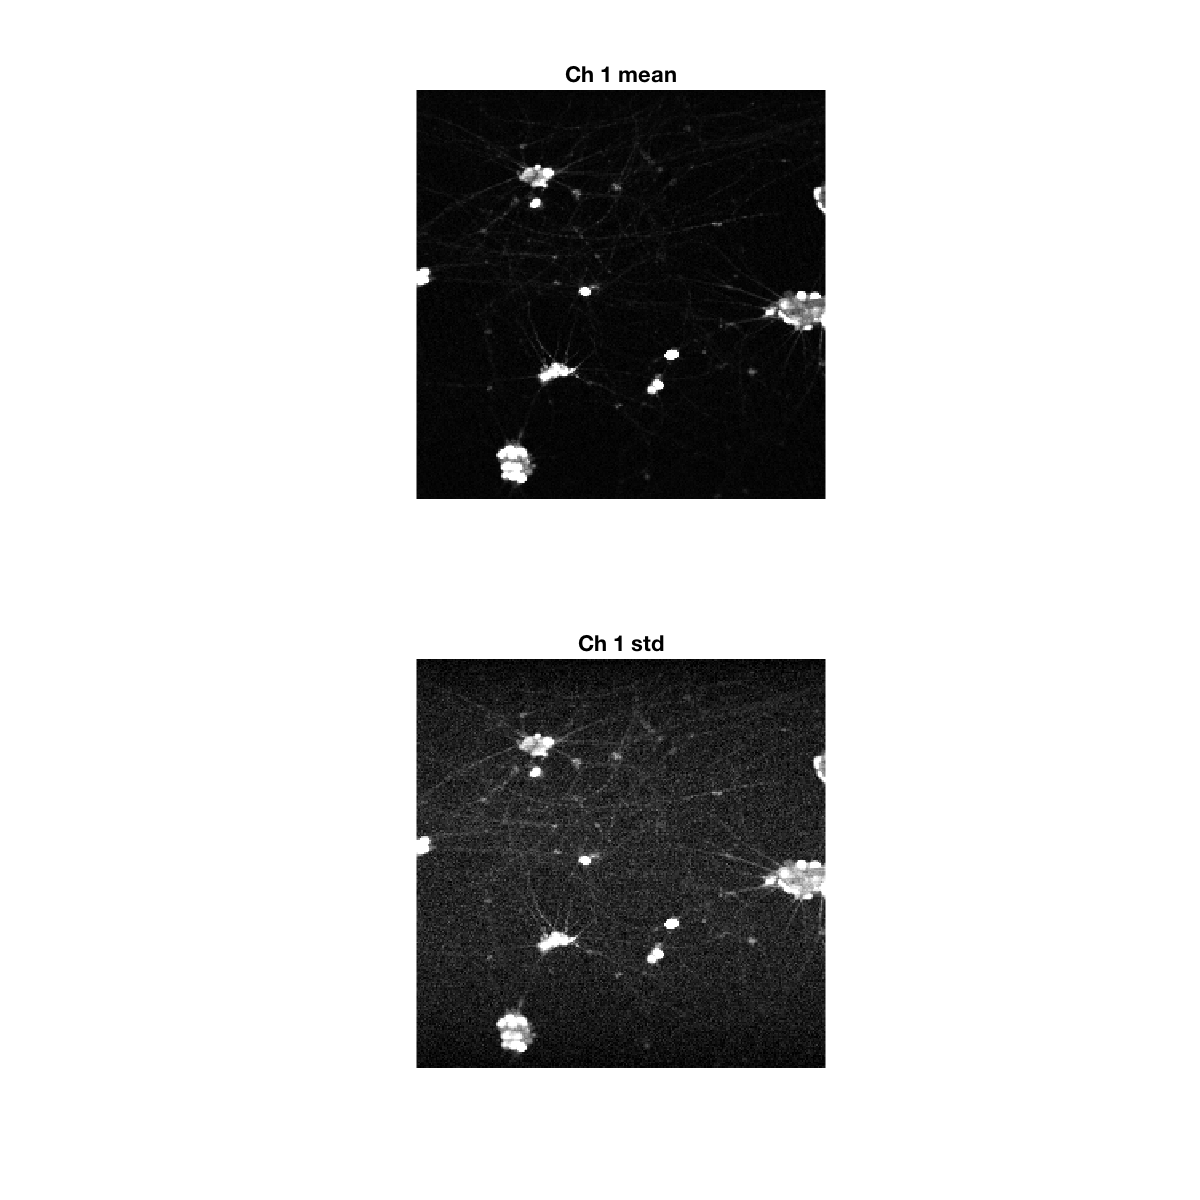

figure; [mean_ch1, std_ch1] = myimgstat(ch1);

[row  col  d3  d4] = [256  256  9000  1]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]


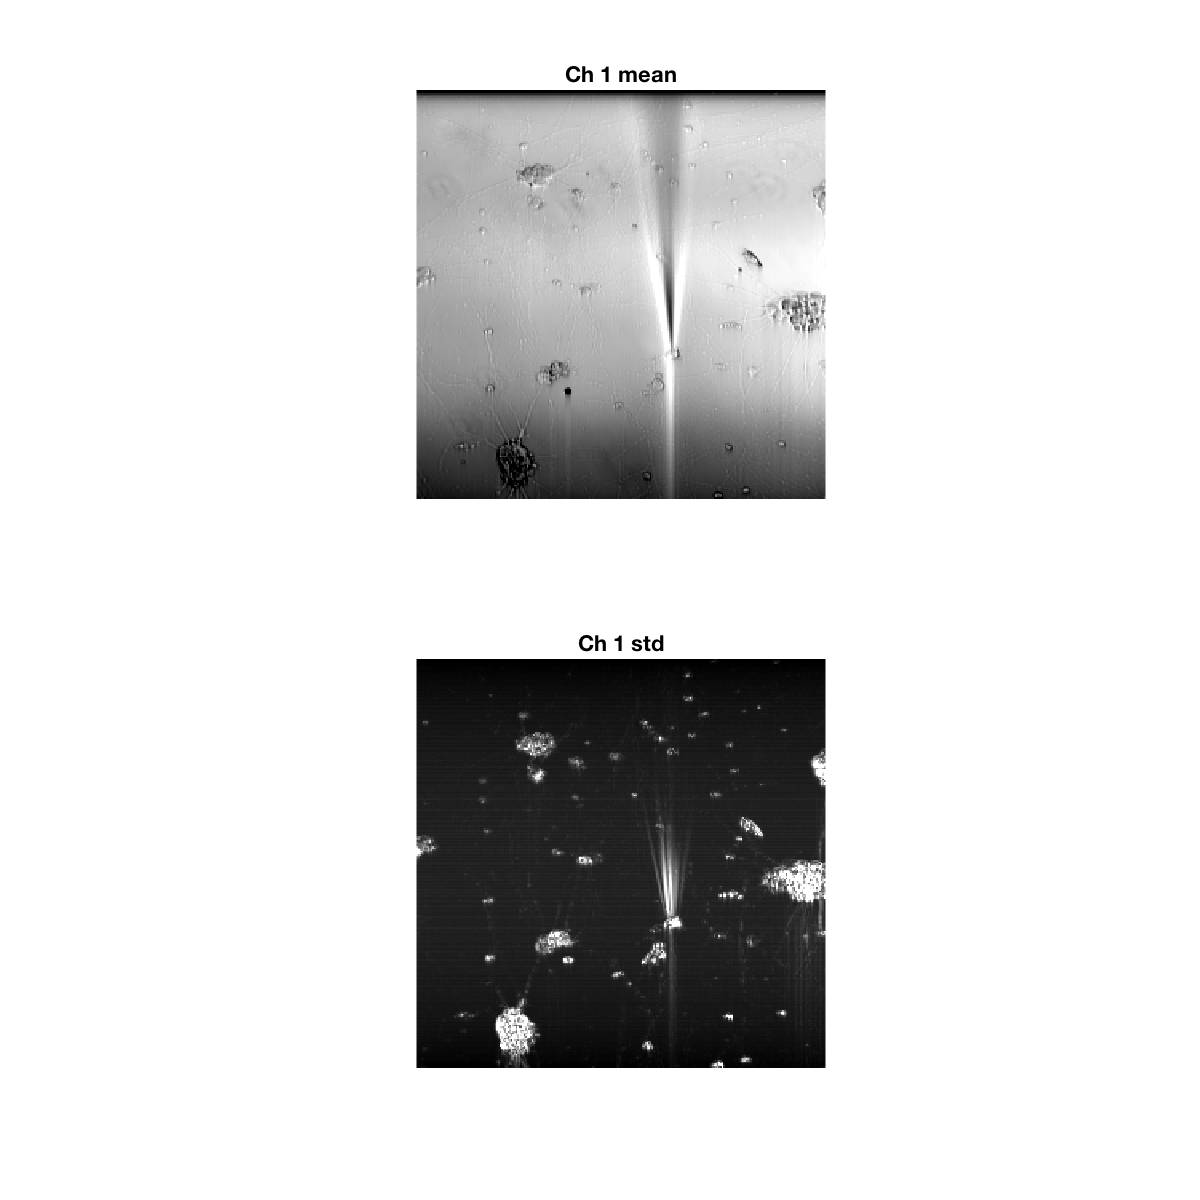

figure; [mean_ch2, std_ch2] = myimgstat(ch2);

[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.020  0.980]


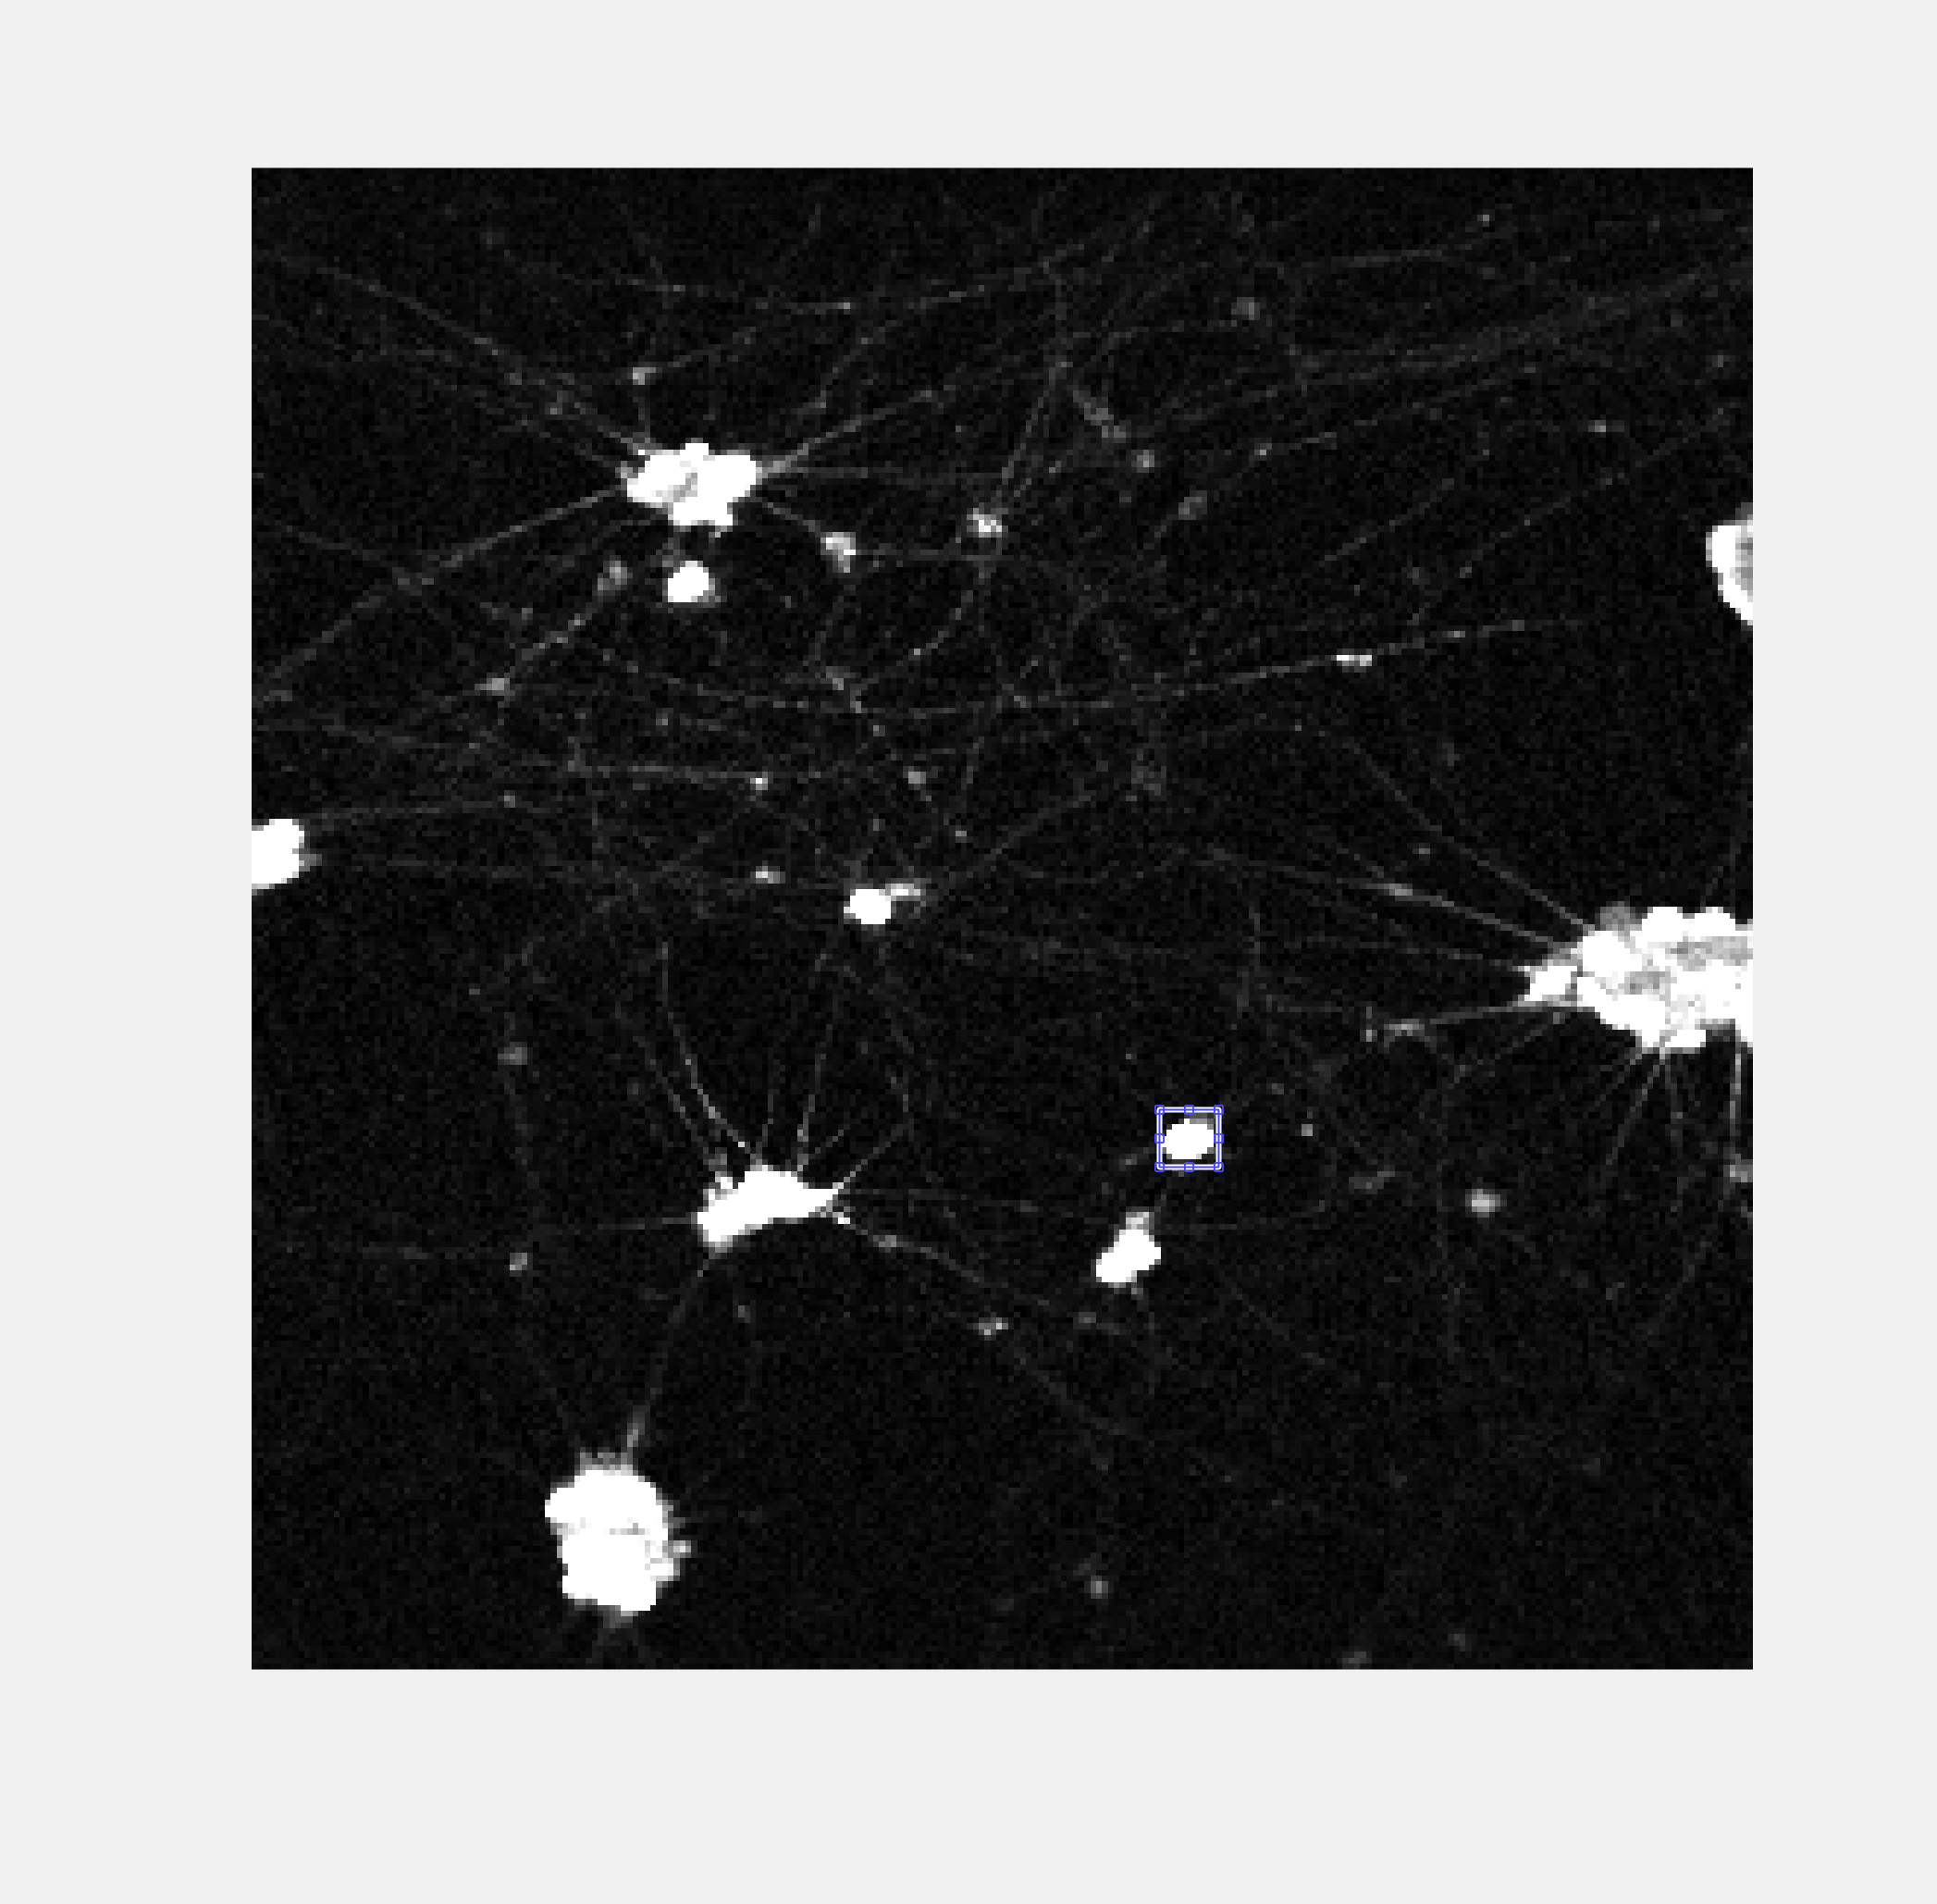

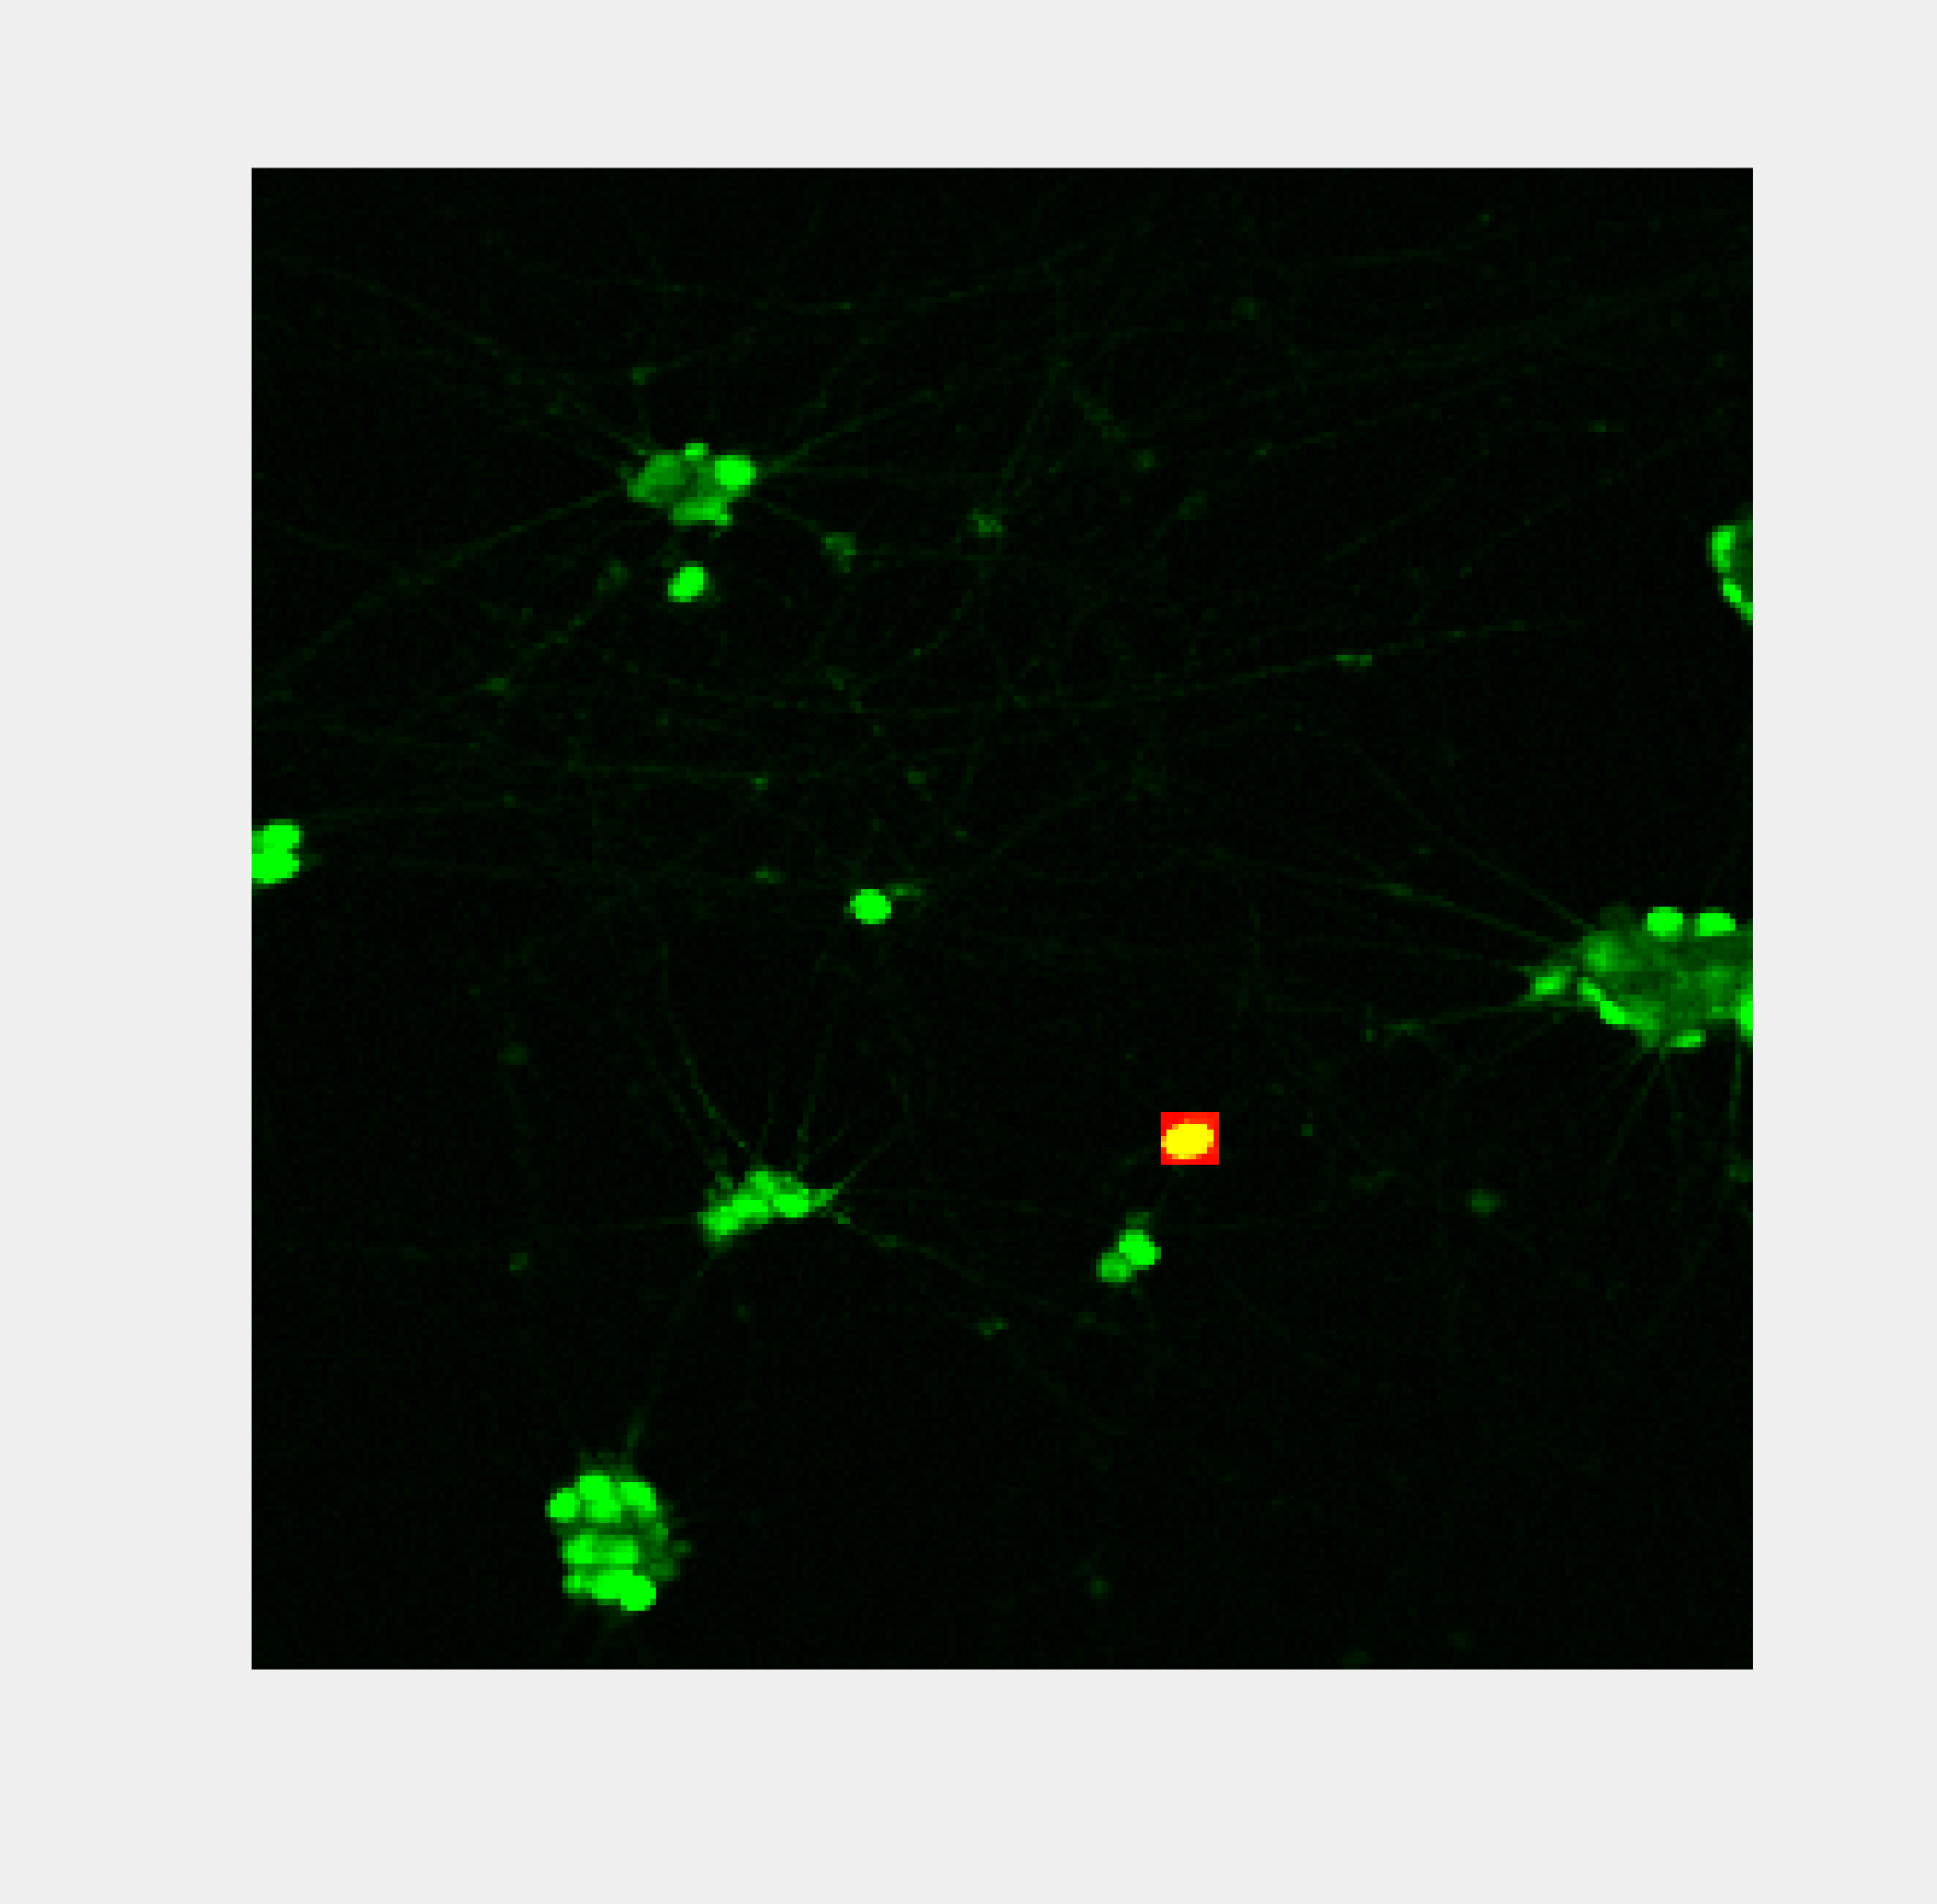

## ROI intensity over time

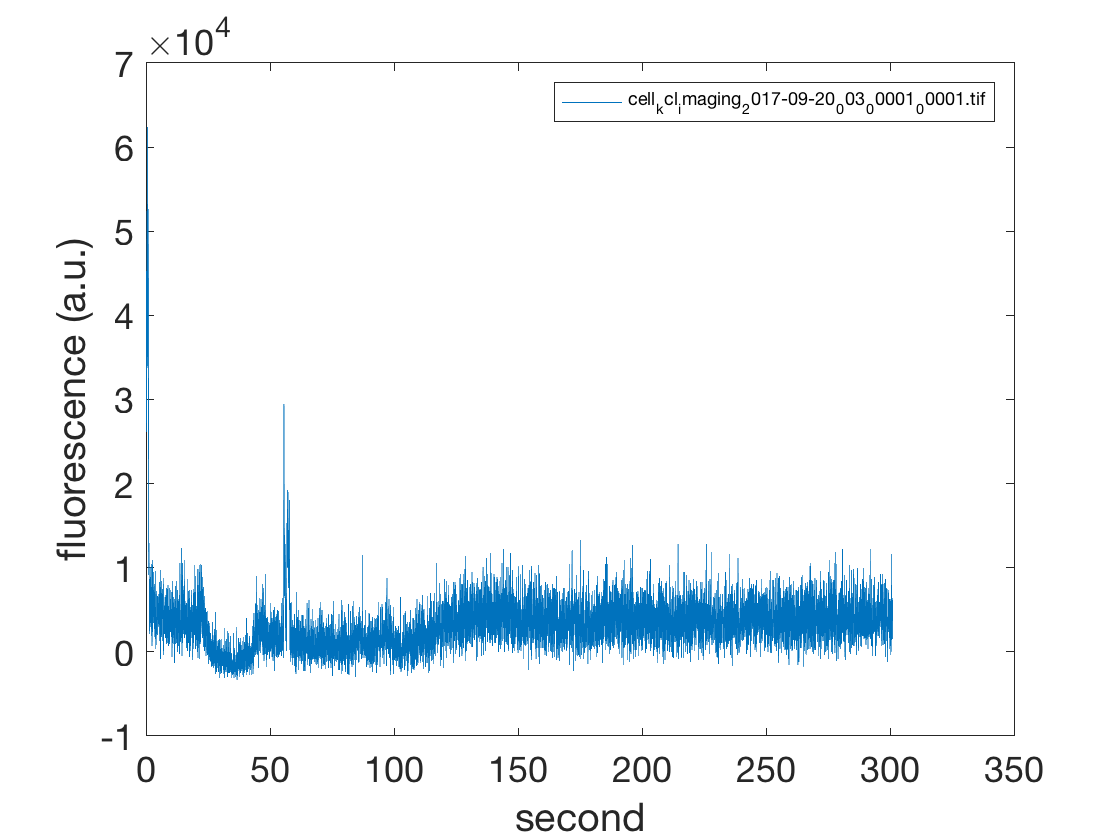



%
figure;
%in = squareRoi(mean_ch1);
roi_array = multiRoi(mean_ch1);
[row, col, n_roi] = size(roi_array);

% roi -> cell array
roi_img = cell(n_roi, N_ch);
roi_avg = cell(n_roi, N_ch);
AI_ch_reshaped = cell(N_ch, 1);
%
roi_reshaped = reshape(roi_array, [], n_roi);

for j=1:N_ch
    
    AI_ch_reshaped{j} = reshape(AI_ch{j}, [], n_frames);
    
    for i=1:n_roi
        roi_img{i,j} = AI_ch_reshaped{j}(roi_reshaped(:,i), :); 
        roi_avg{i,j} = sum(roi_img{i, j}, 1);
    end
end    

%
ifi = 1/29.9;
f_times = (1:n_frames)*ifi;
%
figure; 
plot(f_times,roi_trace);
xlabel('second'); ylabel('fluorescence (a.u.)');
        ax = gca; Fontsize = 18;
        ax.XAxis.FontSize = Fontsize;
        ax.YAxis.FontSize = Fontsize;
        legend(file_list{1});

%

## Did Ca image align with KCl response?

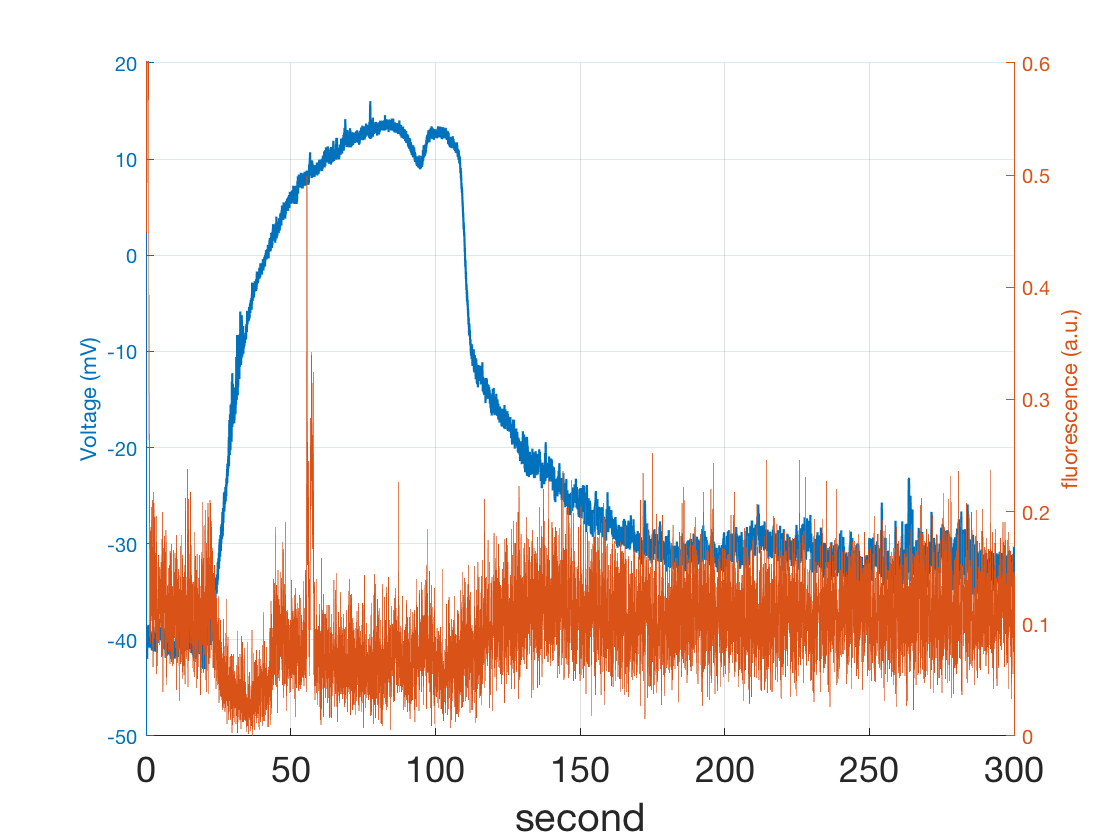

figure; hold on;
yyaxis left
plot(times{7},voltage{7},'LineWidth', 1.1); grid on;
    xlabel('second'); ylabel('Voltage (mV)');
    ax = gca; Fontsize = 18;

yyaxis right
plot(f_times, scaled(roi_trace));
    ylim([0, 0.6])
    xlim([0, 300])
    ylabel('fluorescence (a.u.)');
    ax = gca; Fontsize = 18;
    ax.XAxis.FontSize = Fontsize;

    ax.YAxis.FontSize = Fontsize;

Expected one output from a curly brace or dot indexing expression, but there were 2 results.

hold off;

cla

## ROI2

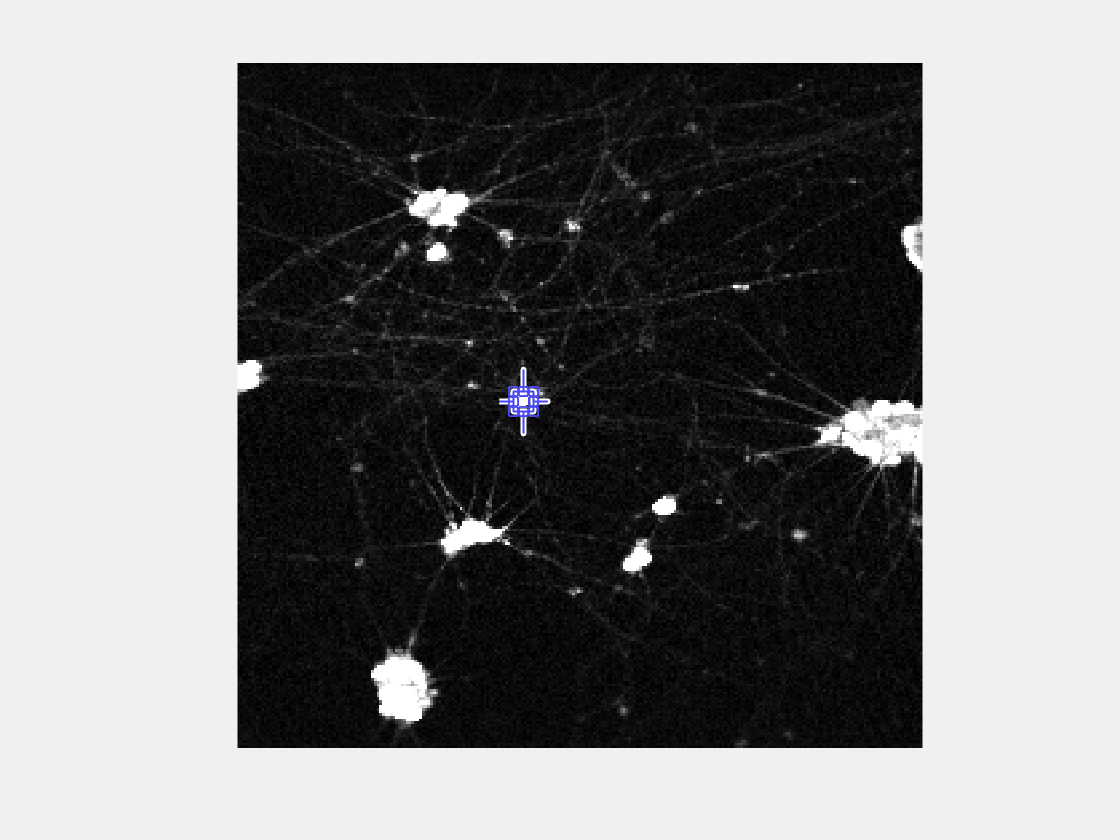

% id for intracellular recording? 
id_recording = 7;

%
figure;

[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.020  0.980]


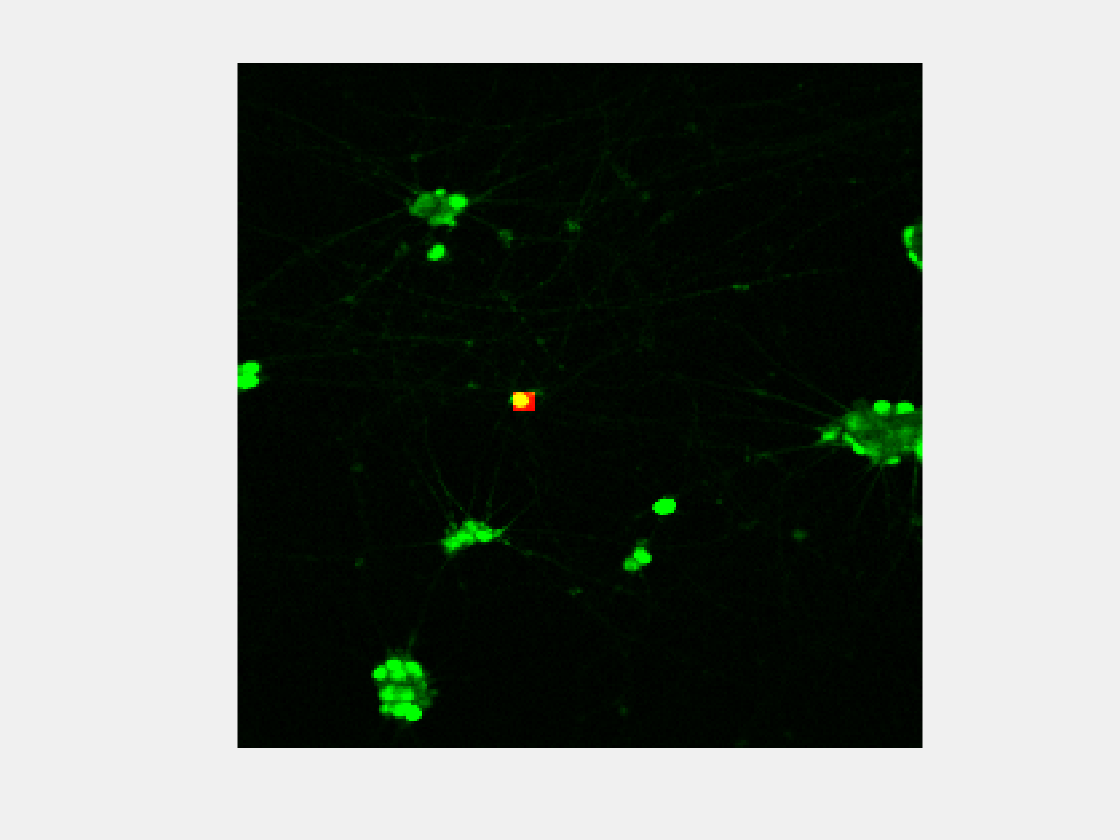

in = squareRoi(mean_ch1);

%
n_frames = dim_ch1(f_dim);

Undefined function or variable 'f_dim'.

%
in_1D = reshape(in, [], 1);
ch1_reshaped = reshape(ch1, [], n_frames);
roi_img = ch1_reshaped(in_1D, :);
roi_trace = sum(roi_img,1);
%
ifi = 1/29.9;
f_times = (1:n_frames)*ifi;
%
figure; 
plot(f_times,roi_trace);
xlabel('second'); ylabel('fluorescence (a.u.)');
        ax = gca; Fontsize = 18;
        ax.XAxis.FontSize = Fontsize;
        ax.YAxis.FontSize = Fontsize;        legend(file_list{1});
%
figure; hold on;
yyaxis left
plot(times{7},voltage{7},'LineWidth', 1.1); grid on;
    xlabel('second'); ylabel('Voltage (mV)');
    ax = gca; Fontsize = 18;

yyaxis right
plot(f_times, scaled(roi_trace));
    ylim([0, 0.6])
    xlim([0, 300])
    ylabel('fluorescence (a.u.)');
    ax = gca; Fontsize = 18;
    ax.XAxis.FontSize = Fontsize;
    ax.YAxis.FontSize = Fontsize;
hold off;

cla